4. Write a computer program to carry out the Monte Carlo Random Walk solution method for following BVP

PDE            $u_{\textrm{xx}} +x^2 u_{\textrm{yy}} =0$        $0<x<1$,$0<y<1$

BCs            $u\left(0,y\right)=0$            $0<y<1$

                    
$$u\left(1,y\right)=0$$
            
$$0<y<1$$


                    
$$u\left(x,0\right)=5$$
            
$$0<x<1$$


                    
$$u\left(x,1\right)=1$$
            
$$0<x<1$$


You may use a uniform grid size h=k or let the x grid size (h) and y grid size (k) be diffierent. How accurate  is  your  solution? How do you know? Also, code the problem using the Finite Difference method. Compare your solution to that from MC. Discuss.

Since the PDE has been changed, the  the probability that the walks goes to each way are different

Consider


$$\begin{array}{l}
u_{\textrm{xx}} =\frac{u_{i,j+1} -2u_{\textrm{ij}} +u_{i,j-1} }{h^2 }\\
u_{\textrm{yy}} =\frac{u_{i+1,j} -2u_{\textrm{ij}} +u_{i-1,j} }{h^2 }\\
x^2 =x_j^2 
\end{array}$$


$\frac{u_{i,j+1} -2u_{\textrm{ij}} +u_{i,j-1} }{h^2 }$+$x_j^2$$\frac{u_{i+1,j} -2u_{\textrm{ij}} +u_{i-1,j} }{h^2 }=0$

If we solve that

$u_{i,j} =\frac{u_{i,j+1} +u_{i,j-1} +x_j^2 \left\lbrack u_{i+1,j} +u_{i-1,j} \right\rbrack }{2\left(1+x_j^2 \right)}$            (3)

So according to the coefficients of each point, the probability could be determined by the coefficients:

with $P_N =\frac{x_j^2 }{2\left(1+x_j^2 \right)}$,move from (i,j) to (i+1,j), which is North direction

with $P_S =\frac{x_j^2 }{2\left(1+x_j^2 \right)}$,move from (i,j) to (i-1,j), which is Sorth direction

with $P_E =\frac{1}{2\left(1+x_j^2 \right)}$,move from (i,j) to (i,j+1), which is East direction

with $P_W =\frac{1}{2\left(1+x_j^2 \right)}$,move from (i,j) to (i,j-1), which is West direction 

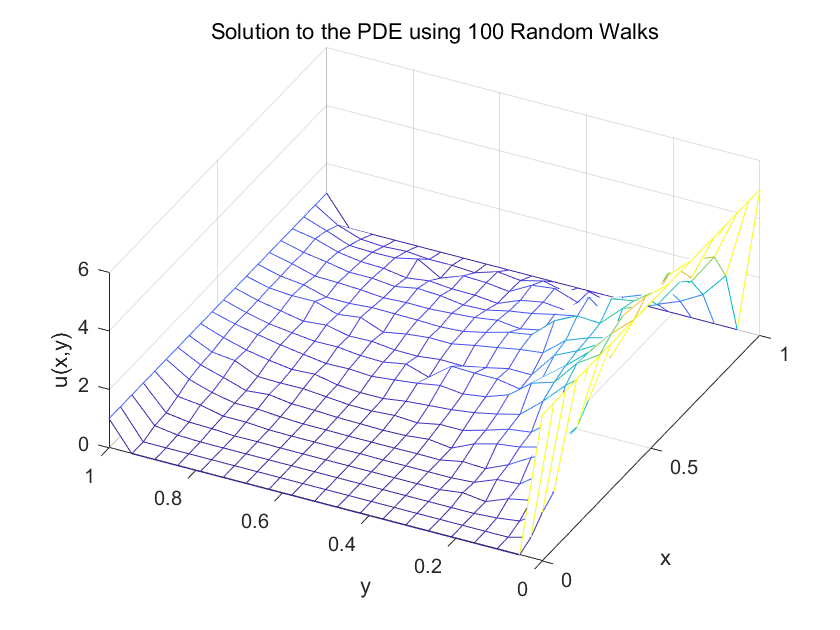

clear

% Step 0:

% Inputs
numWalks     = 100;%set numWaks
numPts       = 20; % number of discretization points in each direction on the board.

% Discretization 
h            = (1-0)/(numPts-1);
x            = 0:h:1;
y            = 0:h:1;

% Set up the entire grid:
[xx,yy]      = meshgrid(x,y);

% Initialize:
u_sol        = zeros(size(xx));


% Enforce the BC u(x,1)=1;
u_sol(end,:) = 1; % If y=1, the value of u(x,y)=1.
u_sol(1,:) = 5;%BC, u(x,0)=5
u        = u_sol;
ufe=u_sol;

% Determine how many boundary points there are (not counting the corners of the board)
numBndry     = 4*(numPts-2);

% Loop over all of the interior points
for ii = 2:(numPts-1)    
    for jj = 2:(numPts-1)
        % Initialize counter for the given point 
        % to track how many walks end up at each boundary point.
        counter = zeros(size(xx));

        for nn = 1:numWalks % Walks loop            
            % Step 1: Choose point A=(ii,jj)
            xPt = jj;
            yPt = ii;
            
            %set probability of each direction
            N=x(jj)^2/(2*(1+x(jj)^2));%P_n
            S=N;%P_S
            E=1/(2*(1+x(jj)^2));%P_E
            W=E;%P_W
            
            % Step 2:
            while xPt~=1 && xPt~=numPts && yPt~=1 && yPt~=numPts 
                % Step 2b test if the walk attach to the boundary point
                w = rand; % random number w in [0,1] from the uniform distribution
                % Step 2a generate w~U(0,1)
                % WALK
                if w>=0 && w<N
                    %test if w between 0 and P_N
                    yPt = yPt + 1; % walk north
                elseif w>=N && w<N+S
                    %test if w between P_N and P_N+P_S
                    yPt = yPt - 1; % walk south
                elseif w>=N+S && w<N+S+E
                    %test if w between P_N+P_S and P_N+P_S+P_E
                    xPt = xPt + 1; % walk east
                elseif w>=N+S+E && w<=1
                    %test if w between P_N+P_S+P_E and 1
                    xPt = xPt - 1; % walk west
                end
            end 
            
            % Once the walk attach the boundary, Record number
            counter(yPt,xPt) = counter(yPt,xPt) + 1;
            % Step 4 compute the fraction
            counter_frac = counter/numWalks; 
        
            % Step 5: Compute the approximate solution at the point A=(ii,jj)      
            u(ii,jj)=sum(u_sol.*counter_frac,'all');
        end 
    end
end   

%plot
mesh(xx,yy,u);
xlabel('x'); ylabel('y');zlabel('u(x,y)')
title(['Solution to the PDE using ' num2str(numWalks) ' Random Walks'])
view([-63.33 55.19])

From the plot above we could see that, the surface is rough due to the method and number of random walk we use. with low number of random walk it will be hard to an accurate surface and solution we want.

Then using Finite Difference method

The method is same as the problem 5 from last homework, with different BCs.

From equaiton (3)

$u_{i,j}$is the weighted sumation of the point around it.

We could adjust

$k=\left\lbrack \begin{array}{ccc}
0 & -{x_j }^2  & 0\\
-1 & 2\left(1+x_j^2 \right) & -1\\
0 & -{x_j }^2  & 0
\end{array}\right\rbrack$        (4)

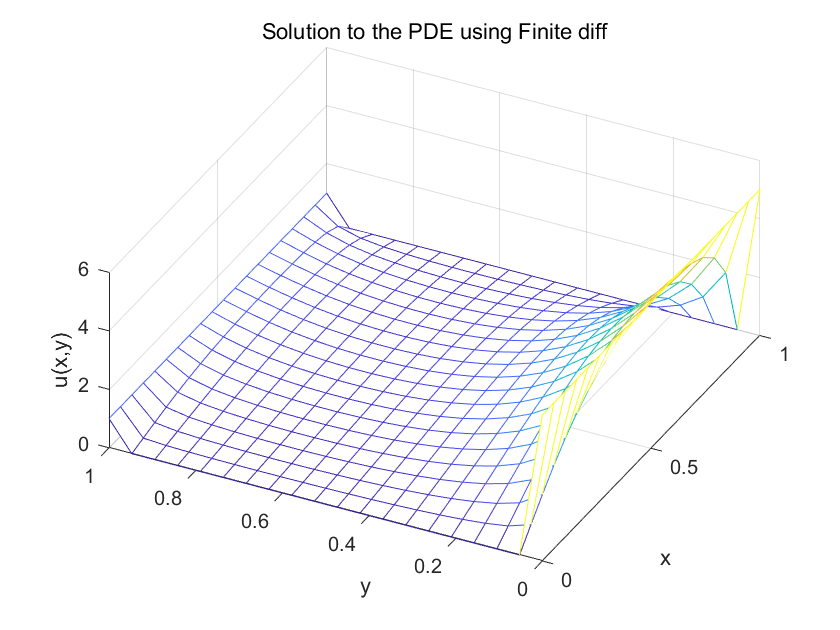

[uk]=FD(numPts,numPts,u_sol,x);
%plot
mesh(xx,yy,uk)
xlabel('x'); ylabel('y');zlabel('u(x,y)')
title(['Solution to the PDE using Finite diff'])
view([-63.33 55.19])

From both plot above, we could see that the shape of these two plots are almost same, Finite difference method will give us more smooth curve.

By accutual compute the difference between these two method

Total_diff = sum(u-uk,'all')

Total_diff = -17.8126

Total_abs_diff = sum(abs(u-uk),'all')

Total_abs_diff = 61.5390

With the different PDE and BCs the accuracy also decreased.

function [uk]=FD(nx,ny,u,x)   
    V=[];
    b=[];
    for j=2:ny-1
        for l=2:nx-1
            k=[0 -(x(l))^2 0;
                -1 2*(1+(x(l))^2) -1;
                0 -(x(l))^2 0];
            %new k from equation(4)
            ut=zeros(ny,nx);
            ut(j-1:j+1,l-1:l+1)=k;
            uc=ut(2:nx-1,2:ny-1);
            V=[V;reshape(uc', 1,(nx-2)*(ny-2))];
            b=[b;(x(l))^2*u(j+1,l)+u(j,l-1)+(x(l))^2*u(j-1,l)+u(j,l+1)];
            %each term in b is the weighted sumation of the point around it
        end
    end
    uin=V\b;
    u(2:nx-1,2:ny-1)=reshape(uin,(nx-2),(ny-2))';
    uk=u;
end